# Ejemplo de solución en MATLAB

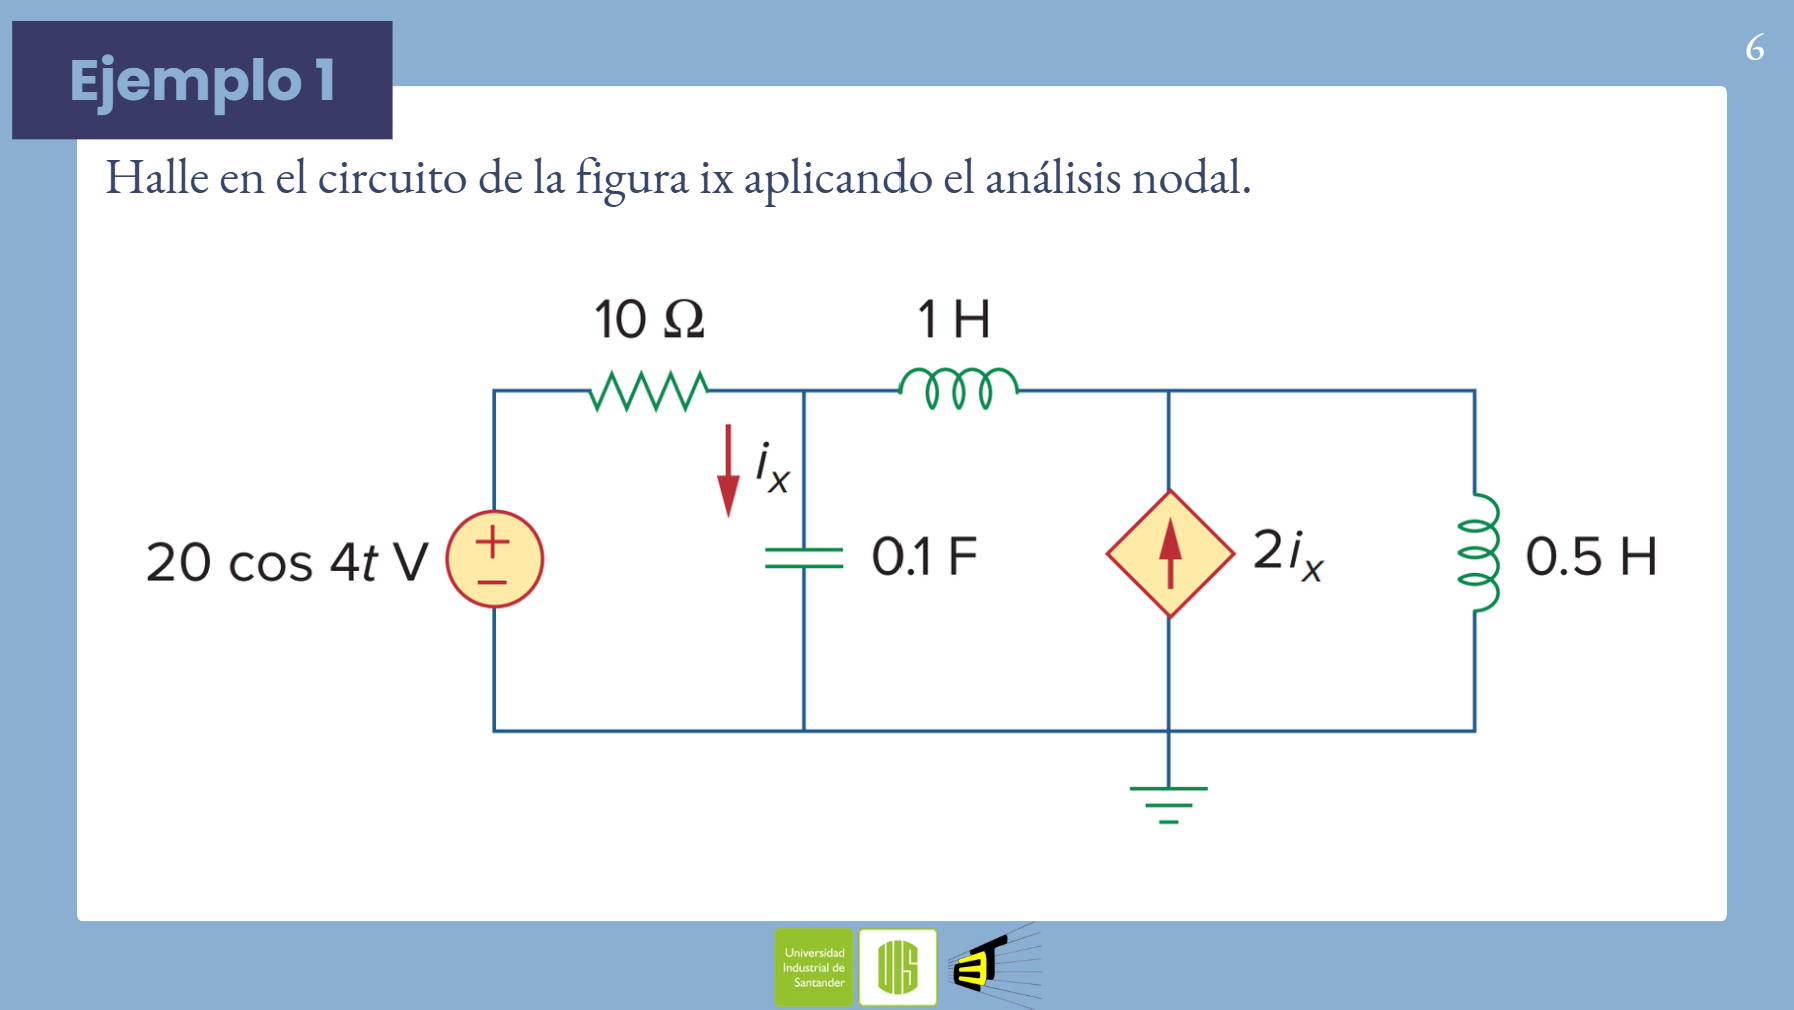

% =========================================================================
% Ejemplo de solución en MATLAB
% Universidad Industrial de Santander
% =========================================================================
% 
% MIT License
% 
% Copyright (c) 2026 Edinson Fabián Adarme
% 
% Permission is hereby granted, free of charge, to any person obtaining a copy
% of this software and associated documentation files (the "Software"), to deal
% in the Software without restriction, including without limitation the rights
% to use, copy, modify, merge, publish, distribute, sublicense, and/or sell
% copies of the Software, and to permit persons to whom the Software is
% furnished to do so, subject to the following conditions:
% 
% The above copyright notice and this permission notice shall be included in all
% copies or substantial portions of the Software.
% 
% THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR
% IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,
% FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE
% AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER
% LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,
% OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE
% SOFTWARE.
% =========================================================================

clc    % Borrar la ventana de comando
clear  % Borrar todas las variables anteriores
close  % Cerrar todas las figuras abiertas

### Paso 1) Transformar los elementos al dominio de la frecuencia compleja

Vs = pha2rect(20,0); % Función para ingresar un fasor ( Fasor-> rectangular )
w = 4; 
ZR = 10;
XC = 1/(w*0.1);   ZC = -1j*XC;
XL1 = w*1;        ZL1 = 1j*XL1;
XL2 = w*0.5;      ZL2 = 1j*XL2;

### Paso 3) Resolver el circuito

% Aplicando la técnica de análisis de nodos
A = [1/ZR + 1/ZC + 1/ZL1 , -1/ZL1;
     -1/ZL1 - 2/ZC       , 1/ZL1 + 1/ZL2 ];
b = [pha2rect(2,0);
     0];

Vab = A\b;
Va = Vab(1);
Vb = Vab(2);

[MVa,AVa] = rect2pha(Va); % Función para obtener la forma fasorial
[MVb,AVb] = rect2pha(Vb); % Función para obtener la forma fasorial
table(MVa,AVa,MVb,AVb)

ans = 1×4 table
     MVa       AVa       MVb        AVb  
    ______    ______    ______    _______

    18.974    18.435    13.914    -161.57


% Aplicando Ley de Ohm
Ix = Va/ZC;

[MIx,AIx] = rect2pha(Ix); % Función para obtener la forma fasorial
table(MIx,AIx)

ans = 1×2 table
     MIx       AIx  
    ______    ______

    7.5895    108.43


% Paso 4) Transformar la solución al dominio del tiempo

ix(t) = 7.590cos(wt + 108.435°) A

function z = pha2rect(Mag,Ang)

z = Mag*exp(1j*Ang*pi/180);

end

function [Mag,Ang] = rect2pha(z)
Mag = abs(z);
Ang = angle(z)*180/pi;
end


